# A script to test and verify each of the functions used in the RUST ADCS

addpath('/home/brad/_gigabit_adcs/matlab/Misc/');
addpath('/home/brad/_gigabit_adcs/matlab/');

## Testing the equatorial rotation matrix calculation and parameterization

ax = eye(3); % a matrix for axis angle to rotation matrix conversions, holds the axes

fr = 0.45; % radians
dec = -0.7;
ra = 1.5;

C_eq = axis2rot(ax(:,1), fr) * axis2rot(ax(:,2), -dec) * axis2rot(ax(:,3),ra)

C_eq =     0.0541    0.7629   -0.6442
   -0.8784    0.3432    0.3327
    0.4749    0.5479    0.6887



%%% derive the parameterization

syms RA DEC FR real
C_e_symb = axis2rotsymb(ax(:,1), FR) * axis2rotsymb(ax(:,2), -DEC) * axis2rotsymb(ax(:,3),RA)

$$C\_e\_symb = \left(\begin{array}{ccc} \cos\left(\mathrm{DEC}\right)\,\cos\left(\mathrm{RA}\right) & \cos\left(\mathrm{DEC}\right)\,\sin\left(\mathrm{RA}\right) & \sin\left(\mathrm{DEC}\right)\\ -\cos\left(\mathrm{FR}\right)\,\sin\left(\mathrm{RA}\right)-\cos\left(\mathrm{RA}\right)\,\sin\left(\mathrm{DEC}\right)\,\sin\left(\mathrm{FR}\right) & \cos\left(\mathrm{FR}\right)\,\cos\left(\mathrm{RA}\right)-\sin\left(\mathrm{DEC}\right)\,\sin\left(\mathrm{FR}\right)\,\sin\left(\mathrm{RA}\right) & \cos\left(\mathrm{DEC}\right)\,\sin\left(\mathrm{FR}\right)\\ \sin\left(\mathrm{FR}\right)\,\sin\left(\mathrm{RA}\right)-\cos\left(\mathrm{FR}\right)\,\cos\left(\mathrm{RA}\right)\,\sin\left(\mathrm{DEC}\right) & -\cos\left(\mathrm{RA}\right)\,\sin\left(\mathrm{FR}\right)-\cos\left(\mathrm{FR}\right)\,\sin\left(\mathrm{DEC}\right)\,\sin\left(\mathrm{RA}\right) & \cos\left(\mathrm{DEC}\right)\,\cos\left(\mathrm{FR}\right) \end{array}\right)$$

%%% then the parameterized angles can be solved for via:
fr_p = atan2(C_eq(2,3), C_eq(3,3))

fr_p = 0.4500

dec_p = asin(C_eq(1,3))

dec_p = -0.7000

ra_p = atan2(C_eq(1,2), C_eq(1,1))

ra_p = 1.5000

## Testing the Gimbal function implementations

ax = eye(3); % a matrix for axis angle to rotation matrix conversions, holds the axes

roll = -1.45; % radians
pitch = -0.14;
yaw = pi-1.32

yaw = 1.8216


C_gmb = axis2rot(ax(:,2), pitch) * axis2rot(ax(:,1), roll) * axis2rot(ax(:,3),yaw)

C_gmb =    -0.3799    0.9249    0.0168
   -0.1167   -0.0299   -0.9927
   -0.9176   -0.3791    0.1193



%%% derive the parameterization

syms P R Y real
C_g_symb = axis2rotsymb(ax(:,2), P) * axis2rotsymb(ax(:,1), R) * axis2rotsymb(ax(:,3),Y)

$$C\_g\_symb = \left(\begin{array}{ccc} \cos\left(P\right)\,\cos\left(Y\right)-\sin\left(P\right)\,\sin\left(R\right)\,\sin\left(Y\right) & \cos\left(P\right)\,\sin\left(Y\right)+\cos\left(Y\right)\,\sin\left(P\right)\,\sin\left(R\right) & -\cos\left(R\right)\,\sin\left(P\right)\\ -\cos\left(R\right)\,\sin\left(Y\right) & \cos\left(R\right)\,\cos\left(Y\right) & \sin\left(R\right)\\ \cos\left(Y\right)\,\sin\left(P\right)+\cos\left(P\right)\,\sin\left(R\right)\,\sin\left(Y\right) & \sin\left(P\right)\,\sin\left(Y\right)-\cos\left(P\right)\,\cos\left(Y\right)\,\sin\left(R\right) & \cos\left(P\right)\,\cos\left(R\right) \end{array}\right)$$

%%% then the parameterized angles can be solved for via:
pitch_p = atan2(-C_gmb(1,3), C_gmb(3,3))

pitch_p = -0.1400

roll_p = asin(C_gmb(2,3))

roll_p = -1.4500

yaw_p = atan2(-C_gmb(2,1), C_gmb(2,2))

yaw_p = 1.8216


%%% gimbal mapping matrix
syms Pd Rd Yd real
wb1 = sym(ax(:,2)) * Pd

$$wb1 = \left(\begin{array}{c} 0\\ \mathrm{Pd}\\ 0 \end{array}\right)$$

wb2 = axis2rotsymb(ax(:,2), P) * sym(ax(:,1)) * Rd

$$wb2 = \left(\begin{array}{c} \mathrm{Rd}\,\cos\left(P\right)\\ 0\\ \mathrm{Rd}\,\sin\left(P\right) \end{array}\right)$$

wb3 = axis2rotsymb(ax(:,2), P)*axis2rotsymb(ax(:,1), R) * sym(ax(:,3)) * Yd

$$wb3 = \left(\begin{array}{c} -\mathrm{Yd}\,\cos\left(R\right)\,\sin\left(P\right)\\ \mathrm{Yd}\,\sin\left(R\right)\\ \mathrm{Yd}\,\cos\left(P\right)\,\cos\left(R\right) \end{array}\right)$$

wb = wb1 + wb2 + wb3

$$wb = \left(\begin{array}{c} \mathrm{Rd}\,\cos\left(P\right)-\mathrm{Yd}\,\cos\left(R\right)\,\sin\left(P\right)\\ \mathrm{Pd}+\mathrm{Yd}\,\sin\left(R\right)\\ \mathrm{Rd}\,\sin\left(P\right)+\mathrm{Yd}\,\cos\left(P\right)\,\cos\left(R\right) \end{array}\right)$$


S = sym(eye(3));
for loc = 1:3
    temp1 = coeffs(wb(loc), Rd);
    if length(temp1) > 1
        S(loc,1) = temp1(2);
    end
    temp2 = coeffs(wb(loc), Pd);
    if length(temp2) > 1
        S(loc,2) = temp2(2);
    end
    temp3 = coeffs(wb(loc), Yd);
    if length(temp3) > 1
        S(loc,3) = temp3(2);
    end
end
S

$$S = \left(\begin{array}{ccc} \cos\left(P\right) & 0 & -\cos\left(R\right)\,\sin\left(P\right)\\ 0 & 1 & \sin\left(R\right)\\ \sin\left(P\right) & 0 & \cos\left(P\right)\,\cos\left(R\right) \end{array}\right)$$

S_test = subs(S, {R, P, Y}, {[roll, pitch, yaw]});
format long
eval(S_test)

ans =    0.990215996212637                   0   0.016815331760778
                   0   1.000000000000000  -0.992712991037588
  -0.139543114644236                   0   0.119323769815489


rsh = reshape(ans', [9, 1])

rsh =    0.990215996212637
                   0
   0.016815331760778
                   0
   1.000000000000000
  -0.992712991037588
  -0.139543114644236
                   0
   0.119323769815489



PHI = simplify(S' * S)

$$PHI = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & \sin\left(R\right)\\ 0 & \sin\left(R\right) & 1 \end{array}\right)$$

## Testing the Horizontal subomdule

az = 0.75 % radians

az =    0.750000000000000


el = -pi/2+0.1

el =   -1.470796326794896


ir = -1.5

ir =   -1.500000000000000



C_hr = axis2rot(ax(:,1), ir) * axis2rot(ax(:,2), -el) * axis2rot(ax(:,3),-az)

C_hr =    0.073046999702127  -0.068050326332037  -0.995004165278026
  -0.677992520184125   0.728292044747507  -0.099583332600765
   0.731430296343333   0.681879645277375   0.007061936526523



%%% derive the parameterization

syms A E I real
C_h_symb = axis2rotsymb(ax(:,1), I) * axis2rotsymb(ax(:,2), -E) * axis2rotsymb(ax(:,3),-A)

$$C\_h\_symb = \left(\begin{array}{ccc} \cos\left(A\right)\,\cos\left(\text{E}\right) & -\cos\left(\text{E}\right)\,\sin\left(A\right) & \sin\left(\text{E}\right)\\ \cos\left(\text{I}\right)\,\sin\left(A\right)-\cos\left(A\right)\,\sin\left(\text{E}\right)\,\sin\left(\text{I}\right) & \cos\left(A\right)\,\cos\left(\text{I}\right)+\sin\left(A\right)\,\sin\left(\text{E}\right)\,\sin\left(\text{I}\right) & \cos\left(\text{E}\right)\,\sin\left(\text{I}\right)\\ -\sin\left(A\right)\,\sin\left(\text{I}\right)-\cos\left(A\right)\,\cos\left(\text{I}\right)\,\sin\left(\text{E}\right) & \cos\left(\text{I}\right)\,\sin\left(A\right)\,\sin\left(\text{E}\right)-\cos\left(A\right)\,\sin\left(\text{I}\right) & \cos\left(\text{E}\right)\,\cos\left(\text{I}\right) \end{array}\right)$$

%%% then the parameterized angles can be solved for via:
ir_p = atan2(C_hr(2,3), C_hr(3,3))

ir_p =   -1.500000000000000



el_p = asin(C_hr(1,3))

el_p =   -1.470796326794896


az_p = atan2(-C_hr(1,2), C_hr(1,1))

az_p =    0.750000000000000


## Normal 321

syms A B G real
C_321_symb = axis2rotsymb(ax(:,1), A) * axis2rotsymb(ax(:,2), B) * axis2rotsymb(ax(:,3),G)

$$C\_321\_symb = \left(\begin{array}{ccc} \cos\left(B\right)\,\cos\left(G\right) & \cos\left(B\right)\,\sin\left(G\right) & -\sin\left(B\right)\\ \cos\left(G\right)\,\sin\left(A\right)\,\sin\left(B\right)-\cos\left(A\right)\,\sin\left(G\right) & \cos\left(A\right)\,\cos\left(G\right)+\sin\left(A\right)\,\sin\left(B\right)\,\sin\left(G\right) & \cos\left(B\right)\,\sin\left(A\right)\\ \sin\left(A\right)\,\sin\left(G\right)+\cos\left(A\right)\,\cos\left(G\right)\,\sin\left(B\right) & \cos\left(A\right)\,\sin\left(B\right)\,\sin\left(G\right)-\cos\left(G\right)\,\sin\left(A\right) & \cos\left(A\right)\,\cos\left(B\right) \end{array}\right)$$

## Testing the State Module top layer

phi2 = eval(subs(PHI, {R}, {roll}))

phi2 =    1.000000000000000                   0                   0
                   0   1.000000000000000  -0.992712991037588
                   0  -0.992712991037588   1.000000000000000



% the equatorial to horizontal conversion
lat = 47.002282304922659;
long = 82.210336016074365;

t_dmy = datetime('now', 'Timezone', 'Z','Format','yyyy/MM/dd HH:mm:ss.SS')

t_dmy = datetime
   2022/05/17 12:30:43.11


t_julian = juliandate(t_dmy);
[thGMST, thGAST] = siderealTime(t_julian)

thGMST =   63.385433134686537


thGAST =   63.385368479390316


last = thGAST + long;

che = compute_rotation_mat_321d(0, lat-90, last + 180)

che =    0.603441246181629  -0.413251298691918   0.681969226971574
   0.565028861171366   0.825071139989388                   0
  -0.562673127535119   0.385332295669666   0.731380867581176


ceh = che'

ceh =    0.603441246181629   0.565028861171366  -0.562673127535119
  -0.413251298691918   0.825071139989388   0.385332295669666
   0.681969226971574                   0   0.731380867581176


az

az =    0.750000000000000


el

el =   -1.470796326794896


ir

ir =   -1.500000000000000


% hor2eq
[ra_c, dec_c, fr_c] = hor2eq(az, el, ir, lat, long, t_dmy)

ra_c =   -0.693168311141921


dec_c =   -0.744917554862544


fr_c =   -0.815437259995434


%eq2gmb
[roll_c, pitch_c, yaw_c] = eq2gmb(ra, dec, fr, lat, long, t_dmy)

roll_c =    1.054795235321903


pitch_c =    0.434339036258517


yaw_c =    2.017469582329920


% gmb2eq
[fr_c2, dec_c2, ra_c2] = gmb2eq(roll, pitch, yaw, lat, long, t_dmy)

fr_c2 =   -2.160008239806648


dec_c2 =   -0.249385823338845


ra_c2 =    1.273537982952817


## Error Module

fr = -0.990;
dec = -0.7;
ra = 1.5; 

[roll_k, pitch_k, yaw_k] = eq2gmb(ra, dec, fr, lat, long, t_dmy)

roll_k =   -0.336649679650007


pitch_k =    0.221792632423025


yaw_k =    2.475329033590512


thet_k = [roll_k, pitch_k, yaw_k]';

fr_d = -0.99;
dec_d = -0.7;
ra_d = 1.505;

[roll_d, pitch_d, yaw_d] = eq2gmb(ra_d, dec_d, fr_d, lat, long, t_dmy)

roll_d =   -0.339333355059546


pitch_d =    0.219562930356998


yaw_d =    2.478246587127139


thet_d = [roll_d, pitch_d, yaw_d]';

eq_rot = axis2rot(ax(:,1), fr) * axis2rot(ax(:,2), -dec) * axis2rot(ax(:,3),ra)

eq_rot =    0.054102796045910   0.762926247359556  -0.644217687237691
  -0.585413219780090  -0.498420780149223  -0.639427938099477
  -0.808927839530031   0.411728389846152   0.419661153108042


eq_rot_d = axis2rot(ax(:,1), fr_d) * axis2rot(ax(:,2), -dec_d) * axis2rot(ax(:,3),ra_d)

eq_rot_d =    0.050287504419847   0.763187223654422  -0.644217687237691
  -0.582913808613095  -0.501341603805257  -0.639427938099477
  -0.810976361324669   0.407678620906993   0.419661153108042


eq_err_rot = eq_rot_d * eq_rot'

eq_err_rot =    0.999992687720591   0.002103446146726   0.003193746961921
  -0.002093147898495   0.999992610866494  -0.003224429296338
  -0.003200505776277   0.003217720733668   0.999989701464998


format long
err_unxmat = unxmat(eq_err_rot');

rol_err = atan2(eq_err_rot(2,3), eq_err_rot(3,3));
pit_err = asin(-eq_err_rot(1,3));
yaw_err = atan2(eq_err_rot(1,2), eq_err_rot(1,1));
gmm = eval(subs(S, {R P Y}, {roll_k, pitch_k, yaw_k}));
gmm_i = inv(gmm);
err_th = [rol_err; pit_err; yaw_err]

err_th =   -0.003224451328565
  -0.003193752391326
   0.002103458425542


norm(err_th)

ans =    0.005002167335802


map_full = gmm_i*err_th

map_full =   -0.002682751305110
  -0.002227394865176
   0.002925459967518


map_unxmat = gmm_i*err_unxmat;
conv_then_map = thet_d - thet_k

conv_then_map =   -0.002683675409539
  -0.002229702066027
   0.002917553536626


conv_then_map - map_full

ans = 	1.0e+-5 *

  -0.092410442941284
  -0.230720085041703
  -0.790643089140395


rad2deg(norm(ans))

ans =      4.748599896582760e-04


ans*3600

ans =    1.709495962769794



rad2deg(norm(conv_then_map))

ans =    0.260590651337451


gmmInv = simplify(inv(S))

$$gmmInv = \left(\begin{array}{ccc} \cos\left(P\right) & 0 & \sin\left(P\right)\\ \frac{\sin\left(P\right)\,\sin\left(R\right)}{\cos\left(R\right)} & 1 & -\frac{\cos\left(P\right)\,\sin\left(R\right)}{\cos\left(R\right)}\\ -\frac{\sin\left(P\right)}{\cos\left(R\right)} & 0 & \frac{\cos\left(P\right)}{\cos\left(R\right)} \end{array}\right)$$

S

$$S = \left(\begin{array}{ccc} \cos\left(P\right) & 0 & -\cos\left(R\right)\,\sin\left(P\right)\\ 0 & 1 & \sin\left(R\right)\\ \sin\left(P\right) & 0 & \cos\left(P\right)\,\cos\left(R\right) \end{array}\right)$$

% testing max difference over many errors

r = deg2rad(6);
p = deg2rad(40);
y = 0.0;

rd = deg2rad([-6:1:6]);
pd = deg2rad([20:10:60]);
yd = deg2rad([0:0.5:pi]);


r = 0.0012

r =    0.001200000000000


p = -0.6965

p =   -0.696500000000000


y = 0.46625

y =    0.466250000000000


rd = -0.00935

rd =   -0.009350000000000


pd = -0.690047

pd =   -0.690047000000000


yd = -0.01005

yd =   -0.010050000000000



t_dmy = datetime('now', 'Timezone', 'Z','Format','yyyy/MM/dd HH:mm:ss.SS');

[ra_1, dec_1, fr_1] = gmb2eq(r, p, y, lat, long, t_dmy);
C_eq1 = axis2rot(ax(:,1), fr_1) * axis2rot(ax(:,2), -dec_1) * axis2rot(ax(:,3),ra_1);
gmm = eval(subs(S, {R P Y}, {r, p, y}))

gmm =    0.767092259932736                   0   0.641536337311881
                   0   1.000000000000000   0.001199999712000
  -0.641536799218321                   0   0.767091707626375


            gmm_i = inv(gmm)

gmm_i =    0.767092259932736                   0  -0.641536799218321
  -0.000769844528587   1.000000000000000  -0.000920511153765
   0.641537261125093                   0   0.767092812239495


            gmm_i2 = eval(subs(gmmInv, {R,P,Y}, {r,p,y}))

gmm_i2 =    0.767092259932736                   0  -0.641536799218321
  -0.000769844528587   1.000000000000000  -0.000920511153765
   0.641537261125093                   0   0.767092812239495


            

max = 0;
locs = [0,0,0];
err_th_hold = zeros(3,1);
for loc = 1:length(rd)
    rl_d = rd(loc);


    for loc2 = 1:length(pd)
        pt_d = pd(loc2);

        for loc3 = 1:length(yd)
            yw_d = yd(loc3);

            [ra_2, dec_2, fr_2] = gmb2eq(rl_d, pt_d, yw_d, lat, long, t_dmy);
            C_eq2 = axis2rot(ax(:,1), fr_2) * axis2rot(ax(:,2), -dec_2) * axis2rot(ax(:,3),ra_2);
            
            eq_err_rot = C_eq2 * C_eq1';

            rol_err = atan2(eq_err_rot(2,3), eq_err_rot(3,3));
            pit_err = asin(-eq_err_rot(1,3));
            yaw_err = atan2(eq_err_rot(1,2), eq_err_rot(1,1));
            err_th = [rol_err; pit_err; yaw_err];

            thet_d = [rl_d, pt_d, yw_d];
            thet_k = [r,p,y];

            map_full = gmm_i*err_th
            conv_then_map = thet_d' - thet_k'
            err = conv_then_map - map_full

            mag = norm(err);
            if mag > max
                max = mag;
                locs = [loc, loc2, loc3];
                err_th_hold = err_th;
            end
        end
    end
end

map_full =   -0.475675522718464
  -0.123073012195331
  -0.019565060511157


conv_then_map =   -0.010550000000000
   0.006453000000000
  -0.476300000000000


err =    0.465125522718464
   0.129526012195331
  -0.456734939488843


max

max =    0.664624363583842


rd(locs(1)) - r

ans =   -0.010550000000000


pd(locs(2)) - p

ans =    0.006453000000000


yd(locs(3)) - y

ans =   -0.476300000000000


## velocity profile


roll_err = -0.10;
pitch_err = 2.0;
yaw_err = 0.750;

g_const = 1.0;
g_lin = 100;
temp1 = g_lin^2 * pi / (4.0 * g_const^2);
temp2 = sqrt(temp1);
temp3 = (2.0 * g_const) / (g_lin * pi);

roll_rate = -sign(roll_err) * sqrt(2.0 * g_const * (abs(roll_err) * erf(abs(roll_err) * temp2)) + (temp3 * (exp((-roll_err^2 * temp1)) - 1.0)))

roll_rate = 0.4400

pitch_rate = -sign(pitch_err) * sqrt(2.0 * g_const * (abs(pitch_err) * erf(abs(pitch_err) * temp2)) + (temp3 * (exp((-pitch_err^2 * temp1)) - 1.0)))

pitch_rate = -1.9984

yaw_rate = -sign(yaw_err) * sqrt(2.0 * g_const * (abs(yaw_err) * erf(abs(yaw_err) * temp2)) + (temp3 * (exp((-yaw_err^2 * temp1)) - 1.0)))

yaw_rate = -1.2221

syms g_c g_l PI theta_err real

temp1 = g_l^2 * pi / (4.0 * g_c^2);
temp2 = sqrt(temp1);
temp3 = (2.0 * g_c) / (g_l * pi);

rate = -sign(theta_err) * sqrt(2.0 * g_c * (abs(theta_err) * erf(abs(theta_err) * temp2)) + (temp3 * (exp((-theta_err^2 * temp1)) - 1.0)))

$$rate = -\sqrt{2}\,\mathrm{sign}\left(\theta_{\mathrm{err}}\right)\,\sqrt{g_{c}\,\mathrm{erf}\left(\sqrt{\pi }\,\left|\theta_{\mathrm{err}}\right|\,\sqrt{\frac{{g_{l}}^{2}}{4\,{g_{c}}^{2}}}\right)\,\left|\theta_{\mathrm{err}}\right|+\frac{g_{c}\,\left({\mathrm{e}}^{-\frac{\pi \,{g_{l}}^{2}\,{\theta_{\mathrm{err}}}^{2}}{4\,{g_{c}}^{2}}}-1\right)}{g_{l}\,\pi }}$$

simplify(rate)

$$ans = -\sqrt{2}\,\mathrm{sign}\left(\theta_{\mathrm{err}}\right)\,\sqrt{g_{c}\,\mathrm{erf}\left(\frac{\sqrt{\pi }\,\left|g_{l}\right|\,\left|\theta_{\mathrm{err}}\right|}{2\,\left|g_{c}\right|}\right)\,\left|\theta_{\mathrm{err}}\right|+\frac{g_{c}\,\left({\mathrm{e}}^{-\frac{\pi \,{g_{l}}^{2}\,{\theta_{\mathrm{err}}}^{2}}{4\,{g_{c}}^{2}}}-1\right)}{g_{l}\,\pi }}$$

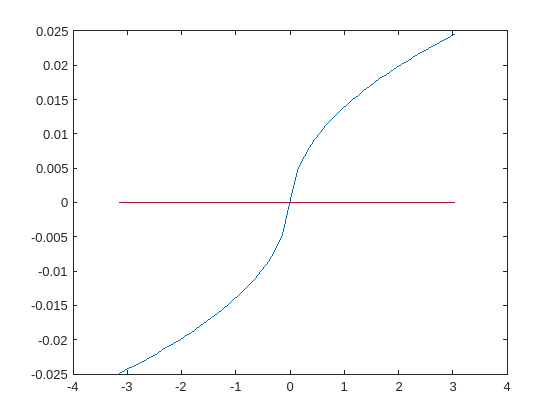

% tiuning velocity profile
terr = -pi: 0.1 : pi;
g_const = 0.0001;
g_lin = 10.;
temp1 = g_lin^2 * pi / (4.0 * g_const^2);
temp2 = sqrt(temp1);
temp3 = (2.0 * g_const) / (g_lin * pi);
rate_test = zeros(length(terr));

for k = 1:length(terr)
    er = terr(k);
    rate_test(k) = sign(er) * sqrt(2.0 * g_const * (abs(er) * erf(abs(er) * temp2)) + (temp3 * (exp((-er^2 * temp1)) - 1.0)));
end
plot(terr, rate_test)

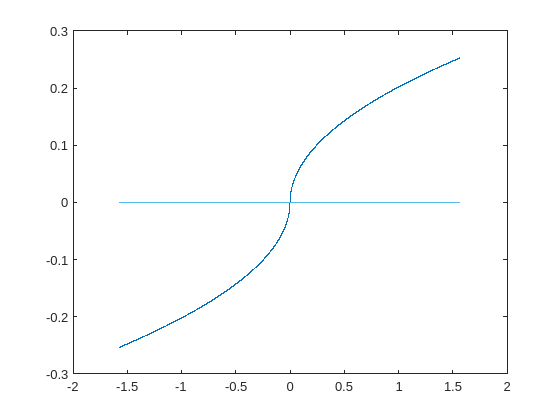

% tiuning velocity profile
terr = -0.5*pi: 0.001 : 0.5*pi;
g_const = 1.0;
g_lin = 1000.0;
temp1 = g_lin^2 * pi / (4.0 * g_const^2);
temp2 = sqrt(temp1);
temp3 = (2.0 * g_const) / (g_lin * pi);
rate_test = zeros(length(terr));

for k = 1:length(terr)
    er = terr(k);
    rate_test(k) = sign(er) * sqrt(2.0 * g_const * (abs(er) * erf(abs(er) * temp2)) + (temp3 * (exp((-er^2 * temp1)) - 1.0)))/7;
end
plot(terr, rate_test)


% testing integration of velocity error
err_decay = 0.999000499833375;
ctrl_dt = 0.01;

rate = [0.44003841000113186; -1.9984078168072512; -1.2221431185734035]

rate =     0.4400
   -1.9984
   -1.2221


rate_sum = zeros(3,1);
rate_sum = (rate_sum * err_decay) + (rate * ctrl_dt)

rate_sum =     0.0044
   -0.0200
   -0.0122


rate_sum = (rate_sum * err_decay) + (rate * ctrl_dt)

rate_sum =     0.0088
   -0.0399
   -0.0244


rate_sum = (rate_sum * err_decay) + (rate * ctrl_dt)

rate_sum =     0.0132
   -0.0599
   -0.0366



% check max acceleration calculation
rate_des_old = 0.2

rate_des_old = 0.2000

rate_des = 0.5

rate_des = 0.5000

max_accel = 0.0005

max_accel = 5.0000e-04

des_accel = rate_des - rate_des_old

des_accel = 0.3000


if abs(des_accel) > max_accel
    if des_accel < 0
        rate_new = rate_des_old - max_accel
    else
        rate_new = rate_des_old + max_accel
    end
end

rate_new = 0.2005

## Testing Error for actual sim

ra = 1.8344765361831148;
dec = 0.2972790664207747; 
fr = -0.04789856834425668;
t_dmy = datetime('2022/05/18 13:17:32.081131164', 'Timezone', 'Z','Format','yyyy/MM/dd HH:mm:ss.SS')

t_dmy = datetime
   2022/05/18 13:17:32.08



[roll_k, pitch_k, yaw_k] = eq2gmb(ra, dec, fr, lat, long, t_dmy)

roll_k =    0.544494723793821


pitch_k =   -0.784739038041745


yaw_k =    2.326325049068627


[az_k, el_k, ir_k] = eq2hor(ra, dec, fr, lat, long, t_dmy);
deg2rad(az_k)

ans =   -0.533750418023934


deg2rad(el_k)

ans =   -0.670878998759966


deg2rad(ir_k)

ans =    0.353499486058000


thet_k = [roll_k, pitch_k, yaw_k]';

fr_d = 0;
dec_d = 0;
ra_d = 0;

[roll_d, pitch_d, yaw_d] = eq2gmb(ra_d, dec_d, fr_d, lat, long, t_dmy)

roll_d =    0.254342079468010


pitch_d =    0.714085925838039


yaw_d =    0.282553070729505


[az_d, el_d, ir_d] = (eq2hor(ra_d, dec_d, fr_d, lat, long, t_dmy));
deg2rad(az_d)

ans =   -0.497251018797207


deg2rad(el_d)

ans =   -0.686530225328633


deg2rad(ir_d)

ans =    0.331336377699065


thet_d = [roll_d, pitch_d, yaw_d]';

eq_rot = axis2rot(ax(:,1), fr) * axis2rot(ax(:,2), -dec) * axis2rot(ax(:,3),ra)

eq_rot =   -0.249203084434163   0.923090389347811   0.292919708797833
  -0.967985477762611  -0.246796066856873  -0.045780085459377
   0.030032275125093  -0.294950562768891   0.955040432637867


## Get orientation vector

rot = [0.7772080 -0.0243042  0.6287743;
  0.0169516  0.9996998  0.0176884;
  -0.6290154 -0.0030888  0.7773867]

rot =    0.777208000000000  -0.024304200000000   0.628774300000000
   0.016951600000000   0.999699800000000   0.017688400000000
  -0.629015400000000  -0.003088800000000   0.777386700000000


ir_p = atan2(rot(2,3), rot(3,3))

ir_p =    0.022749743912391



el_p = asin(rot(1,3))

el_p =    0.679975920147763


az_p = atan2(-rot(1,2), rot(1,1))

az_p =    0.031260978272264


pitch_p = atan2(-rot(1,3), rot(3,3))

pitch_p =   -0.680102424027438


roll_p = asin(rot(2,3))

roll_p =    0.017689322519501


yaw_p = atan2(-rot(2,1), rot(2,2))

yaw_p =   -0.016955065496721


axis2rot(ax(:,2), pitch_p) * axis2rot(ax(:,1), roll_p) * axis2rot(ax(:,3),yaw_p)

ans =    0.777207962133955  -0.024304225086206   0.628774274472600
   0.016951600624377   0.999699836821889   0.017688400000000
  -0.629015442443074  -0.003088834933668   0.777386668439134
